# `Part 1: Frequency estimator`

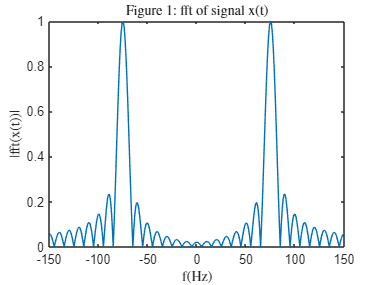

f0 = 75;
fs = 1000;
t = 0:1/fs:0.1-1/fs;
x_t = cos(2*pi*f0.*t);
fftx_t = fftshift(fft(x_t,fs));
f = -500:500 -1;
plot(f, abs(fftx_t)/max(abs(fftx_t)))
xlim([-150 150])
title('Figure 1: fft of signal x(t)', 'Interpreter','latex');
xlabel('f(Hz)','Interpreter','latex');
ylabel('|fft(x(t))|','Interpreter','latex');

`At first, we generate the x(t) and take sample from it by 1k Hz frequency. Then, as it said in report, we should take fft from it and symmetrize the result by using fftshift. In the interval of [-500, 500], we plot the normalized abolute of the result and see that in Figure 1.`

`1)Figure 1 shows that the maximum points are approximately at -75 and 75, so we can say the frequency of `$f_0 \;$`, so that the signal is made from, is 75 Hz.`

`2) Yes, the guessed frequencies and the original one are the same.`

`3)`

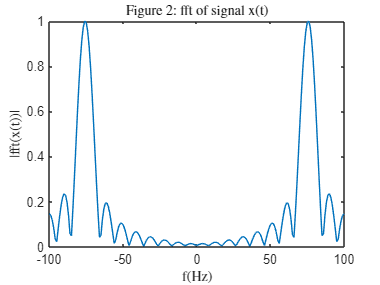

f0 = 75.5;
fs = 1000;
t = 0:1/fs:0.1-1/fs;
x_t = cos(2*pi*f0.*t);
fftx_t = fftshift(fft(x_t,fs));
f = -500:500 -1;
plot(f, abs(fftx_t)/max(abs(fftx_t)))
xlim([-150 150])
title('Figure 2: fft of signal x(t)', 'Interpreter','latex');
xlabel('f(Hz)','Interpreter','latex');
ylabel('|fft(x(t))|','Interpreter','latex');

`No they are not the same. Figure 2 shows the maximums of fft of the signal are in the middle of 50 and 100, which is 75. So we almost say the `$f_0$` is 75 which is wrong.`

`5)`

fft_result = abs(fftx_t)/max(abs(fftx_t));
maximum = max(max(abs(fftx_t)/max(abs(fftx_t))));
[x,y]=find(abs(fftx_t)/max(abs(fftx_t))==maximum);
index = y(1);
f_est1 = 75 + 1.25*(3.*fft_result(index+3)+2.*fft_result(index+2)+fft_result(index+1)- fft_result(index-1) - 2.*fft_result(index-2) - 3.*fft_result(index-3))

f_est1 = 75.5989

`As you can see, the estimated frequency is 75.3473 which is closer to 75.5 than 75 which is the one that we estimated by obseriving the graph. so we can say this method of estimating decreasing the error of estimation.`

`6)`

fftx_t = fftshift(fft(x_t,10*fs));
f = -500:1/10:500 -1/10;
fft_result = abs(fftx_t)/max(abs(fftx_t));
maximum = max(max(abs(fftx_t)/max(abs(fftx_t))));
[x,y]=find(abs(fftx_t)/max(abs(fftx_t))==maximum);
index = y(1);
f_est2 = 75 + 1.25*(3.*fft_result(index+3)+2.*fft_result(index+2)+fft_result(index+1)- fft_result(index-1) - 2.*fft_result(index-2) - 3.*fft_result(index-3))

f_est2 = 75.0011

`As you see, after we multiply the number of fft points by 10, the estimated frequency is not the same as the main one (`$f_0$); `it has error of 0.5 Hz. So we go through the process of dividing the number of points by 10:`

fftx_t = fftshift(fft(x_t,1/10*fs));
f = -500:10:500 -10;
fft_result = abs(fftx_t)/max(abs(fftx_t));
maximum = max(max(abs(fftx_t)/max(abs(fftx_t))));
[x,y]=find(abs(fftx_t)/max(abs(fftx_t))==maximum);
index = y(1);
f_est3 = 75 + 1.25*(3.*fft_result(index+3)+2.*fft_result(index+2)+fft_result(index+1)- fft_result(index-1) - 2.*fft_result(index-2) - 3.*fft_result(index-3))

f_est3 = 75.5989

`The estimated frequency for this case, is much more closer to the main frequency of `$f_0$ `and that is because as the number of points of fft decreases, the distances between for instance `$X_L$`and `$X_{l+1}$`, will be higher so that the sum and taking average of them won't be similar to the one that we guessed ourselves.`

`We cannot zero the error of the estimated frequency and the one that signal structed with. the reason for that is the estimation process contains taking weighted mean of just six points of fft. As we change the number of points in making fft, it's just get closer to the main one; but the same.`

# `Part 2: Continuous time signal's Fourier transform`

    
$$x\left(t\right)=\left\lbrace \begin{array}{cc}
10 & ,0\le t\le 30\mu s\\
0 & ,30\mu s<t\le 3\textrm{ms}
\end{array}\right.$$


`1)`

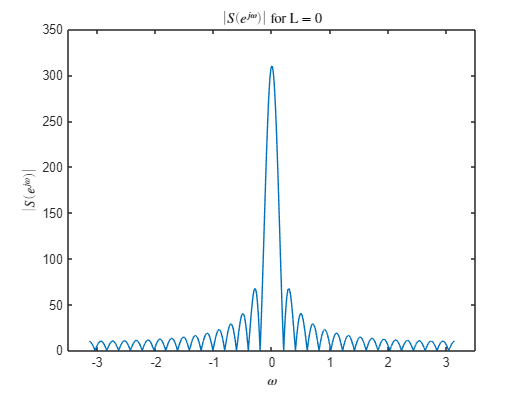

clear;
fs = 1000;
T = 3;
x(1:(30e-3*fs+1)) = 10;
x(T*fs) = 0;

L0 = 0; 
n0 = 0:((L0+1)*T*fs-1);
w = -pi:1/10000:pi;
s0 = [];
for i = 0:L0
    s0 = [s0 x];
end
S0ejw = fftshift(fft(s0,length(w)));
plot(w,abs(S0ejw));
xlim([-3.5 3.5])
title('$|S(e^{j\omega})|$ for L = 0','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|S(e^{j\omega})|$','Interpreter','latex');

`2)`

[ii,jj]=find(abs(S0ejw)<=0.025e-1);
delta_L0 = jj(1)

delta_L0 = 5068

`3)`

ABS_S0 = abs(S0ejw);
Peak_S0 = max(ABS_S0);
i0 = min(find(ABS_S0 > Peak_S0/sqrt(2)));
j0 = max(find(ABS_S0 > Peak_S0/sqrt(2)));
BW_L0 = w(j0)-w(i0)

BW_L0 = 0.1796

BW_L0_per100 = BW_L0/(2*pi)

BW_L0_per100 = 0.0286

### `4) L = 2`

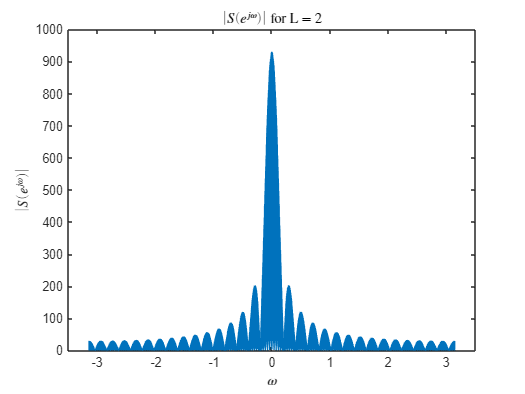

L1 = 2; 
n1 = 0:((L1+1)*T*fs-1);
w = -pi:1/10000:pi;
s1 = [];
for i = 0:L1
    s1 = [s1 x];
end
S1ejw = fftshift(fft(s1,length(w)));
plot(w,abs(S1ejw));
xlim([-3.5 3.5])
title('$|S(e^{j\omega})|$ for L = 2','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|S(e^{j\omega})|$','Interpreter','latex');

[ii,jj]=find(abs(S1ejw)<=0.025e-1);
delta_L1 = jj(1)

delta_L1 = 1014

ABS_S1 = abs(S1ejw);
Peak_S1 = max(ABS_S1);
i1 = min(find(ABS_S1 > Peak_S1/sqrt(2)));
j1 = max(find(ABS_S1 > Peak_S1/sqrt(2)));
BW_L1 = w(j1)-w(i1)

BW_L1 = 0.1760

BW_L1_per100 = BW_L1/(2*pi)

BW_L1_per100 = 0.0280

### `L = 10`

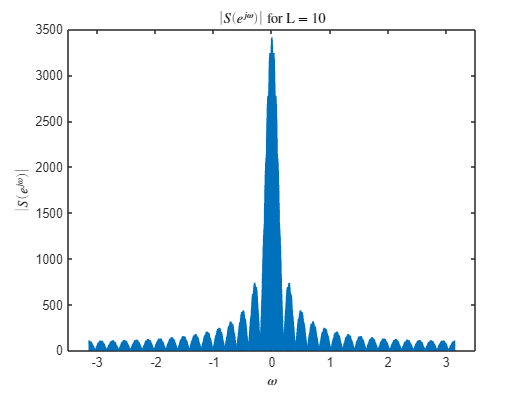

L2 = 10; 
n2 = 0:((L2+1)*T*fs-1);
w = -pi:1/10000:pi;
s2 = [];
for i = 0:L2
    s2 = [s2 x];
end
S2ejw = fftshift(fft(s2,length(w)));
plot(w,abs(S2ejw));
xlim([-3.5 3.5])
title('$|S(e^{j\omega})|$ for L = 10','Interpreter','latex');
xlabel('$\omega$','Interpreter','latex');
ylabel('$|S(e^{j\omega})|$','Interpreter','latex');

[ii,jj]=find(abs(S2ejw)<=0.025e-1);
delta_L2 = jj(1)

delta_L2 = 239

ABS_S2 = abs(S2ejw);
Peak_S2 = max(ABS_S2);
i2 = min(find(ABS_S2 > Peak_S2/sqrt(2)));
j2 = max(find(ABS_S2 > Peak_S2/sqrt(2)));
BW_L2 = w(j2)-w(i2)

BW_L2 = 0.1676

BW_L2_per100 = BW_L2/(2*pi)

BW_L2_per100 = 0.0267

`5) By increasing the L, maximum of the the fft will get higher and also the point of fft will increase too so the signal would be more compacted.`

`The bandwidth of fft Signal with L=0 is 2.86%, with L = 2 is 2.8% and with L = 10 is 2.67%. We get that by increasing the Number of "Inverted-time-advance-fourier transform of x(t)", the bandwidth of signal decreases and it get closer to Delta. `

`6) As it mentioned in previous part, by increasing L, the fft of Signal will be closer to Delta. For proving this statement, we can tell about "Fourier series coeeficient" and "Fourier transform", So by increasing L, s(t) will act like continuous signal.`


$$X\left(j\Omega \right)\sum_{k=0}^N 2\pi a_k \delta \left(\Omega -\Omega_k \right)$$


# `Part 3`: `Estimating range and speed of automobile`

#### `1) It's the time of transmitting wave to the car and going back to the antenna.`


$$\textrm{time}=2\frac{x}{c}=2\frac{R_0 }{c}$$


#### `2) `$y\left(t\right)=\beta e^{\textrm{j2}\pi f_d t} x\left(t-\frac{{2R}_0 }{c}\right)+n\left(t\right)\overset{F\ldotp T\ldotp }{\longrightarrow} Y\left(j\omega \right)=\beta e^{-j\omega \frac{{2R}_0 }{c}} X\left(j\left(\omega -2\pi f_d \right)\right)+N\left(j\omega \right)$ 

#### `3)By plotting Y(j`$\omega$) , `we can see how much the graph is been shifted to the right, thats the `$\omega_d$. `by dividing it to `$2\pi$, $f_d$` will be derived. Noise signal is White Noise and the only thing that changes the form of signal, is scaling by it's power which is `$\frac{N_0 }{2}=\frac{\sigma^2 }{2}$.

4)

#### `A)`

fs = 1000000;
t = 0:1/fs:0.025-1/fs;
plot(t,y)

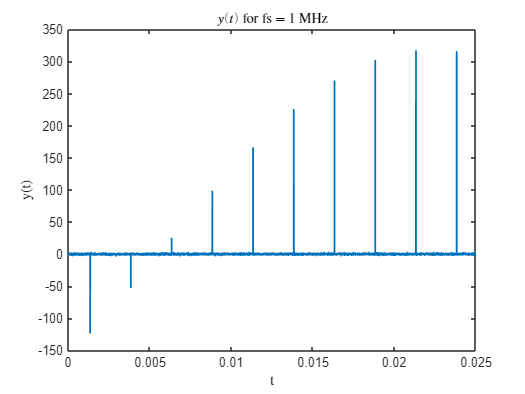

title('$y(t)$ for fs = 1 MHz','Interpreter','latex')
xlabel('t','Interpreter','latex');
ylabel('y(t)','Interpreter','latex');

#### `As you can see in figure, the number of shifted of x(t) is 10, so ``I = 9``.`

index_1 = mean(find(y>-150 & y<-100))

index_1 = 1346

index_2 = mean(find(y>-55 & y<-10))

index_2 = 3846

T_ind = index_2 - index_1;
T = T_ind/fs

T = 0.0025

`For ``finding T``, it's logical to find the times of two peaks and then substract them from each other, but we have to mention that the peaks are not unique and it small period of time, there is 50 or more peaks. According to that, first we have to find indeices of time which they have the same peaks. We go for first and the second peaks. Then, we have to take the mean of them so that we can say the local maximum is just happend there. Then by substracting two means, the "T" will be deriven.`

width_1 = find(y>-150 & y<-100);
length(width_1)

ans = 25

width_2 = find(y>-55 & y<-10);
length(width_2)

ans = 25

width = 25/fs

width = 2.5000e-05

#### `For finding pulse width, as you know, we have multiple peaks in a tiny period of time. So at first we find the number of all of the first peak and second peak to see if they are equal or not; which they are. So the number of all peak in one pulse width is 25 and we have to divide it by the sampling frequency. The pulse width is derived which is 25 `$\mu \sec$.

#### `B) ``Estimating `$R_0 \;\&\;V_0$`:`

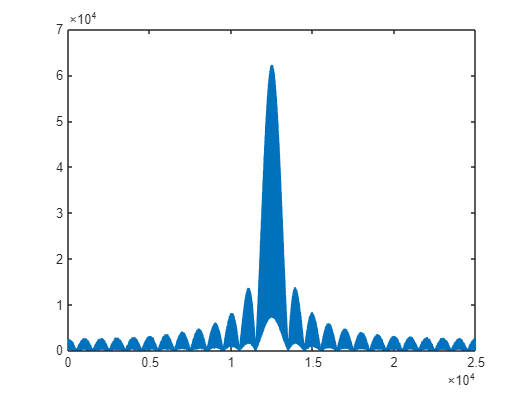

Y_f = fftshift(fft(y));
f = 0:25000-1;
plot(f,abs(Y_f))

index = find(abs(Y_f)==max(abs(Y_f)))

index = 12501

#### `As you can see, the maximum of the fourier transform of y(t) is happened at `$\omega$` of 12501 rad/s. If we divide it to `$2\pi$, `the frequency will be:`

freq = index/(2*pi)

freq = 1.9896e+03